We can solve the logistic differential equation, both analytically and numerically using `ode45`.

Say, these are our given parameters:

rc = 0.8;
K  = 1000;
N0 = 100;
tspan = [0 12];

### Numerical solution

We need to write the differential in $\frac{df}{dt} = f'(t)$ format to be made compatible with the `ode45` function.

Remember,


$$\frac{dN}{dt} = Nr_c (1 - \frac{N}{K})$$


rhs = @(t,N) rc*N*(1-N/K); % rhs means "right-hand side"

`ode45` takes the differential function, the range of values we want out function to be determined at and the initial condition as its parameters.

[t_num,N_num] = ode45(rhs,tspan,N0);

We can plot this:

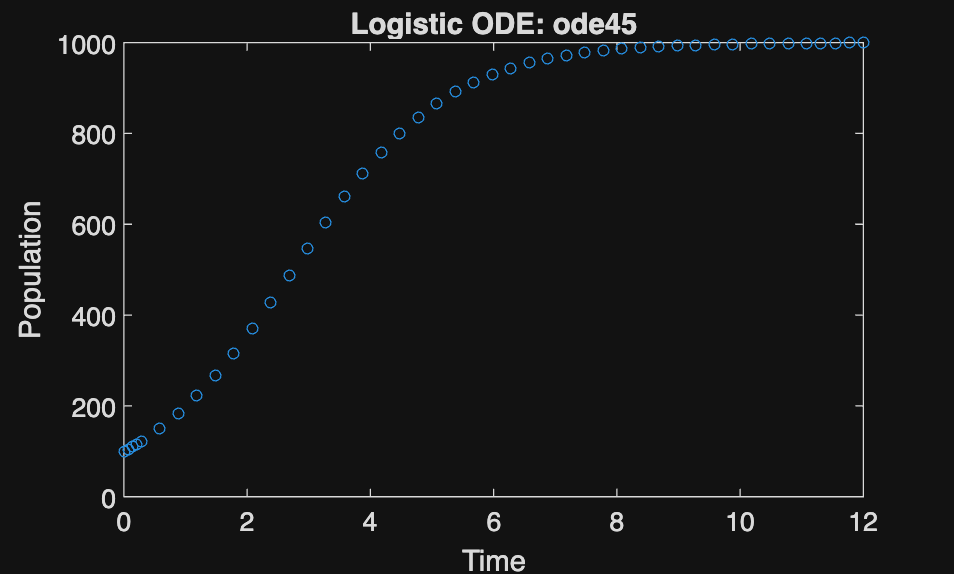

plot(t_num,N_num,'o','MarkerSize',4);
hold on;
xlabel('Time'); ylabel('Population');
title('Logistic ODE: ode45');

### Analytical solution

Remember that the analytical solution was:


$$N(t) = \frac{K}{1 + \left(\frac{K-N_0}{N_0}\right)e^{-r_c t}}$$


t = linspace(0, 12, 500); % Same limits as tspan, just we determine the number of points
N_exact = K ./ (1 + ((K-N0)/N0).*exp(-rc*t));

We can plot this too!

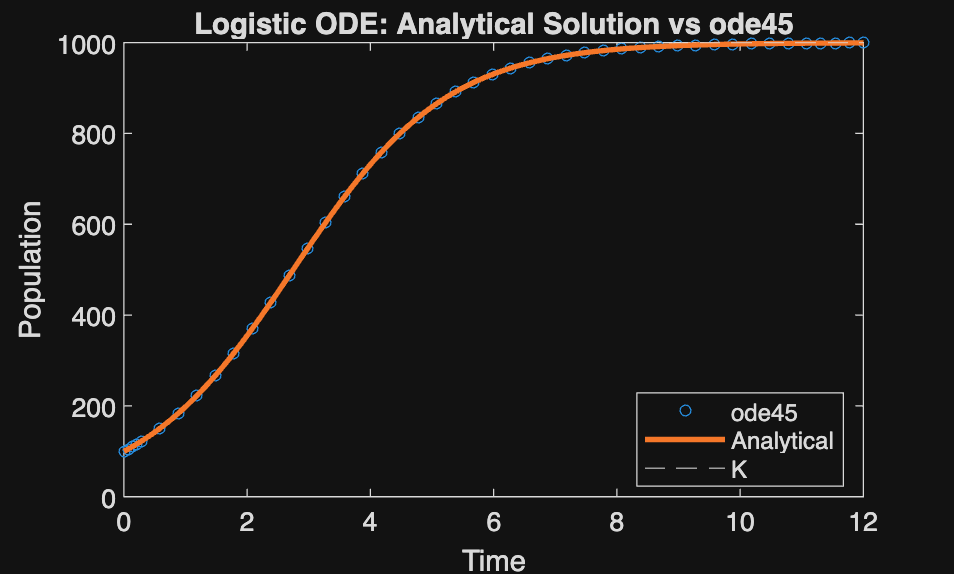

plot(t,N_exact,'LineWidth',2);
yline(K,'--','K');
title('Logistic ODE: Analytical Solution vs ode45');
legend('ode45', 'Analytical', 'K','Location','best');